## Problem 2.17(b), Class example for W5D2, 8 October 2019, EE3032-4, Dr. Durant

Set up the given functions and the analytic solution for the y(t) convolution. We include the u(t) portion in case the code is ever modified to make t start before 0 (try it!).

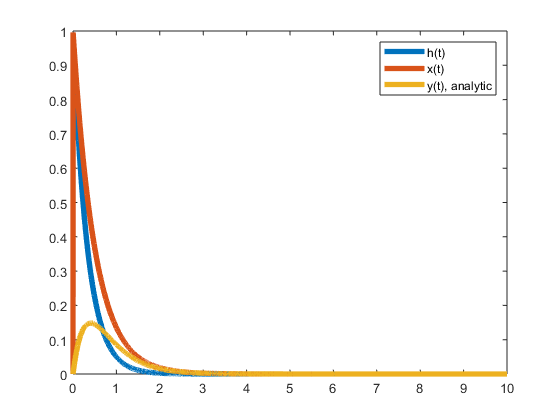

t = linspace(0, 10, 5000);
h = exp(-3*t) .* (t>0);
x = exp(-2*t) .* (t>0);
y = (exp(-2*t) - exp(-3*t)) .* (t>0);
plot(t,h, t,x, t,y)
legend('h(t)', 'x(t)', 'y(t), analytic')

Have MATLAB compute the convolution numerically. Multiplying by the time step gives a Riemann approximation to the integral. Note how we truncate yc to match the input length instead of being the default of twice as long from the width property; this shortcut only works when t starts at 0. Note that the assert  causes the code to fail with a descriptive error when the assumption is violated. This is better than doing the wrong thing (starting at 0 instead of 2*t0.

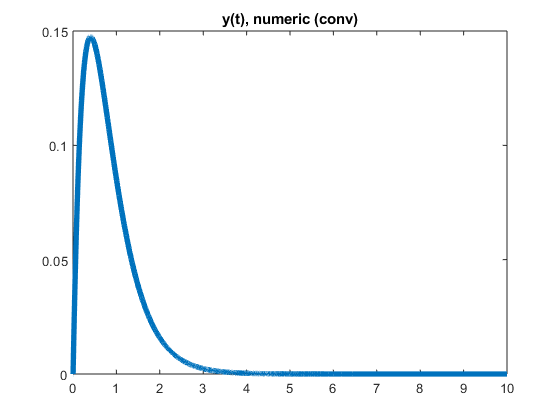

dt = diff(t(1:2));
yc = dt * conv(h,x);
assert(t(1)==0,'Truncation method assumes t starts at 0; must update code if this is no longer a valid assumption')
yc = yc(1:length(t));
plot(t,yc)
title('y(t), numeric (conv)')

Now, look at the error, which is small (note the scale of 10^-3 on the plot) and caused by numerically approximating the discontinuities at t=0. This error will decrease of you add more samples (smaller dt) when initializing t.

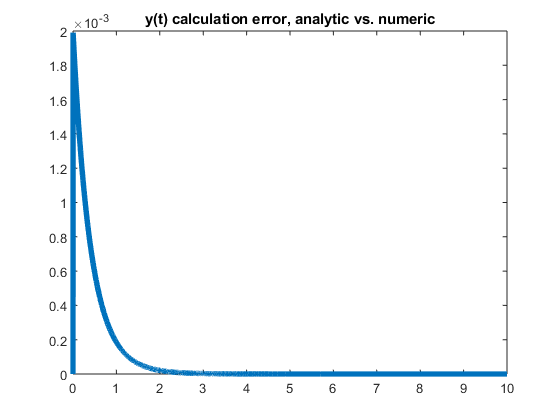

plot(t,y-yc)
title('y(t) calculation error, analytic vs. numeric')

err = y-yc;
fprintf('The sum of the squared elements of the error vector is %g.\n',...
    sum(err.^2))

The sum of the squared elements of the error vector is 0.00040639.


fprintf('The norm() of the error vector, which is the square root of the SSE,\nwhich is also the error vector length, is %g.\n',...
    norm(y-yc))

The norm() of the error vector, which is the square root of the SSE,
which is also the error vector length, is 0.0201591.
